clear
% 109
A=sym([1 2])

$$A = \left(\begin{array}{cc} 1 & 2 \end{array}\right)$$

C=sym([3 6])

$$C = \left(\begin{array}{cc} 3 & 6 \end{array}\right)$$

hold on
plot(A(1),A(2),'ro',0,0,7,7)
plot(C(1),C(2),'bo')
grid
syms x y
Lac=line2p(A,C)

$$Lac = 2\,x=y$$

syms alpha k1 k2
eq1=tan(alpha)==abs((k2-k1)/(1+k1*k2)) 

$$eq1 = \tan\left(\alpha \right)=\frac{\left|k_{1}-k_{2}\right|}{\left|k_{1}\,k_{2}+1\right|}$$

eq2=subs(eq1,[alpha k1],[pi/4 2])

$$eq2 = 1=\frac{\left|k_{2}-2\right|}{\left|2\,k_{2}+1\right|}$$

k2=solve(eq2)

$$k2 = \left(\begin{array}{c} -3\\ \frac{1}{3} \end{array}\right)$$

syms x y x1 y1 k
L=y-y1==k*(x-x1)

$$L = y-y_{1}=k\,\left(x-x_{1}\right)$$

Lab=simplify(subs(L,[k x1 y1],[k2(1) A]))

$$Lab = 3\,x+y=5$$

Lad=simplify(subs(L,[k x1 y1],[k2(2) A]))

$$Lad = x+5=3\,y$$

Lbc=simplify(subs(L,[k x1 y1],[k2(2) C]))

$$Lbc = x+15=3\,y$$

Lcd=simplify(subs(L,[k x1 y1],[k2(1) C]))

$$Lcd = 3\,x+y=15$$

[xb,yb]=solve(Lab,Lbc);B=[xb yb]

$$B = \left(\begin{array}{cc} 0 & 5 \end{array}\right)$$

[xd,yd]=solve(Lad,Lcd);D=[xd yd]

$$D = \left(\begin{array}{cc} 4 & 3 \end{array}\right)$$

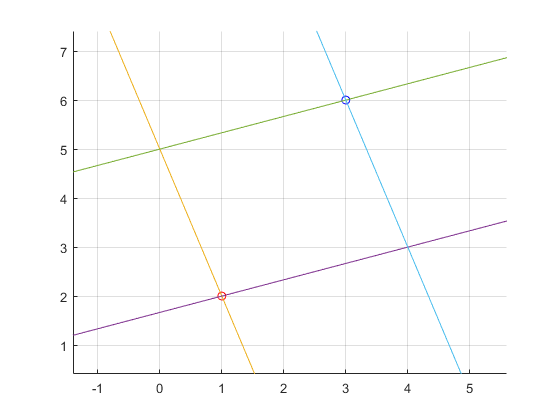

fimplicit(Lab)
fimplicit(Lad)
fimplicit(Lbc)
fimplicit(Lcd)

xlim([-1.40 5.60])
ylim([0.41 7.41])